# OpenSim Tutorial 2 - Simulation and Analysis of a Tendon Transfer Surgery

Author: Ross D. Wilkinson

Affiliation: University of Colorado Boulder

This is a Live Script created to illustrate how Tutorial 2 ca   n be implemented in MATLAB rather than through OpenSim's GUI. Personally, the main advantage of the MATLAB-based solution is the ease of working with the output files and visualising the results. The directions for the tutorial can be found here: [https://simtk-confluence.stanford.edu:8443/display/OpenSim/Tutorial+2+-+Simulation+and+Analysis+of+a+Tendon+Transfer+Surgery](https://simtk-confluence.stanford.edu:8443/display/OpenSim/Tutorial+2+-+Simulation+and+Analysis+of+a+Tendon+Transfer+Surgery)

## II. Musculoskeletal Model of the Wrist

### Initialize API

import org.opensim.modeling.*
import org.opensim.utils.*

### Set directories

projectDir = '/Users/rosswilkinson/Google Drive/projects/mines-modeling/';
docDir = [projectDir 'docs'];
modelDir = [projectDir 'models'];
modelFile = 'wrist.osim';

### Load model and initialize

% model = Model(fullfile(modelDir, modelFile));
% model.setUseVisualizer(true);
% model.initSystem();

### Questions

1. Which motion is expressed in positive angles: wrist flexion or wrist extension?

Q1 = 'flexion';

2. Which motion is expressed in positive angles: radial deviation or ulnar deviation?

Q2 = 'ulnar deviation';

3. What are the functions of the Extensor Carpi Ulnaris (ECU) muscle? 

Q3 = {'wrist extension','ulnar deviation'};

4. What are the functions of the Extensor Carpi Radialis Brevis (ECRB)? 

Q4 = {'wrist extension','radial deviation'};

## III. Simulation of a Tendon Transfer

Work specific to GUI

## IV. Biomechanical Effects of Tendon Transfer

Run analysis in GUI then export data to .txt file

### Load data of wrist flexion moment vs. flexion angle

resDir = [projectDir 'results'];
cd(resDir)
fileName = 'opensimTutorial2_wristFlexionMoment.txt';
t_flex = readtable(fileName);

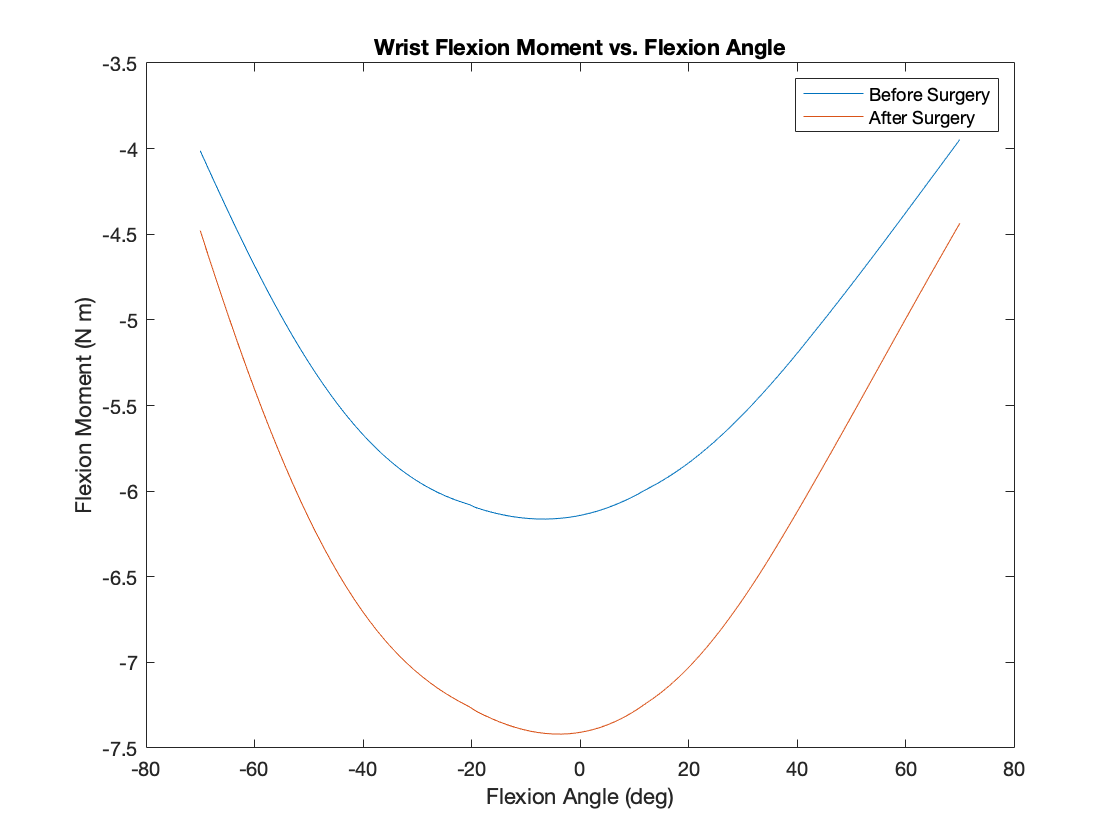


figure
plot(t_flex.x_jointset_Wrist_flexion_value, t_flex.BeforeSurgery)
hold on
plot(t_flex.x_jointset_Wrist_flexion_value, t_flex.AfterSurgery)
title('Wrist Flexion Moment vs. Flexion Angle')
ylabel('Flexion Moment (N m)')
xlabel('Flexion Angle (deg)')
legend('Before Surgery','After Surgery')

### Load plot of wrist deviation moment vs. deviation angle

fileName = 'opensimTutorial2_wristDeviationMoment.txt';
t_dev = readtable(fileName);

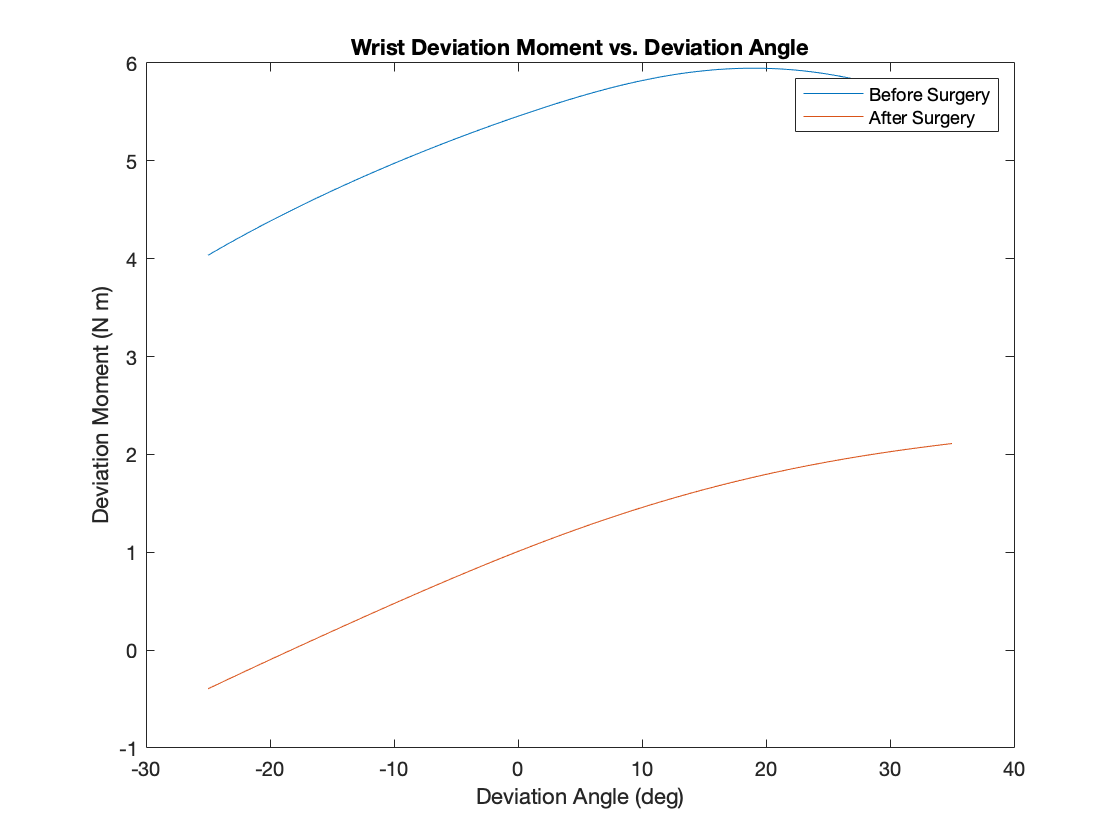


figure
plot(t_dev.x_jointset_Wrist_deviation_value, t_dev.BeforeSurgery)
hold on
plot(t_dev.x_jointset_Wrist_deviation_value, t_dev.AfterSurgery)
title('Wrist Deviation Moment vs. Deviation Angle')
ylabel('Deviation Moment (N m)')
xlabel('Deviation Angle (deg)')
legend('Before Surgery','After Surgery')

### Questions

5. In these plots, given how the model defines the wrist flexion degree of freedom, is wrist extension moment denoted by positive or negative values?

Q5 = 'negative';

6. What happens to the maximum moment of the wrist extensors if the ECU muscle is transferred to the ECRB?

Hint: Remember, one of the goals of the surgery is to increase wrist extension strength. 


min(t_flex.BeforeSurgery)

ans = -6.1632

min(t_flex.AfterSurgery)

ans = -7.4187

Q6 = 'Increases';

7. In these plots, is the sign of an ulnar deviation moment positive or negative?

Q7 = 'positive';

8. What happens to the maximum moment of the ulnar deviators if the ECU muscle is transferred to the ECRB location?

max(t_dev.BeforeSurgery)

ans = 5.9469

max(t_dev.AfterSurgery)

ans = 2.1115

Q8 = 'decreases';

9. One goal of this tendon transfer surgery is to decrease excessive ulnar deviation. Has your simulated surgery achieved this goal? Why or why not? 

Q9 = 'Likely. Because the ECU muscle has a decreased moment arm.';

10. What is the peak value of the ECU extension moment before transfer? At what flexion angle does it occur?

 Note: Remember, extension moments are negative on the plots.

fileName = 'opensimTutorial2_EcuMoment.txt';
opts = detectImportOptions(fileName,'FileType','delimitedtext');
t_ecu = readtable(fileName,opts);

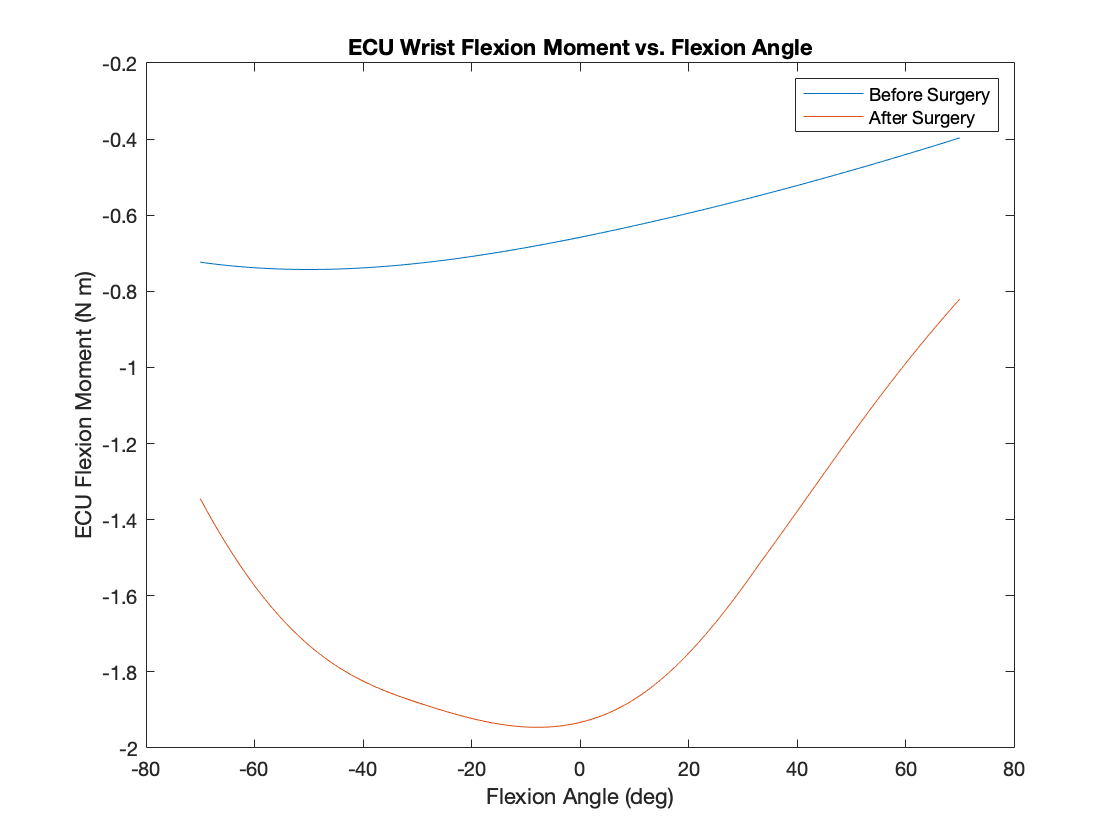


figure
x = t_ecu.x_jointset_Wrist_flexion_value;
y1 = t_ecu.ECU_pre_surgery;
y2 = t_ecu.ECU_post_surgery;
plot(x,y1)
hold on
plot(x,y2)
title('ECU Wrist Flexion Moment vs. Flexion Angle')
ylabel('ECU Flexion Moment (N m)')
xlabel('Flexion Angle (deg)')
legend('Before Surgery','After Surgery')


[M,I] = min(y1);
preTheta = x(I);
Q10 = [M preTheta]

Q10 =    -0.7426  -50.2020


11. What is the peak value of the ECU extension moment after transfer? At what flexion angle does it occur?

[M,I] = min(y2);
postTheta = x(I);
Q11 = [M postTheta]

Q11 =    -1.9456   -7.7778


12. Does the moment-generating capacity of the ECU vary more with flexion angle before or after the simulated surgery?

preRange = range(y1)

preRange = 0.3459

postRange = range(y2)

postRange = 1.1254


Q12 = 'after'

Q12 = 'after'

13. Write down the peak values of each curve (**flexion moment, tendon force, moment arm**), the joint angle at which the peak occurs, and describe the general shapes of the curves.

t = table();
t.Flexion_moment = [min(y1); min(y2)];
t.Flexion_moment_angle = [preTheta; postTheta];
t.Properties.RowNames = {'BeforeSurgery','AfterSurgery'};

fileName = 'opensimTutorial2_EcuTendonForce.txt';
t_ecuTF = readtable(fileName);

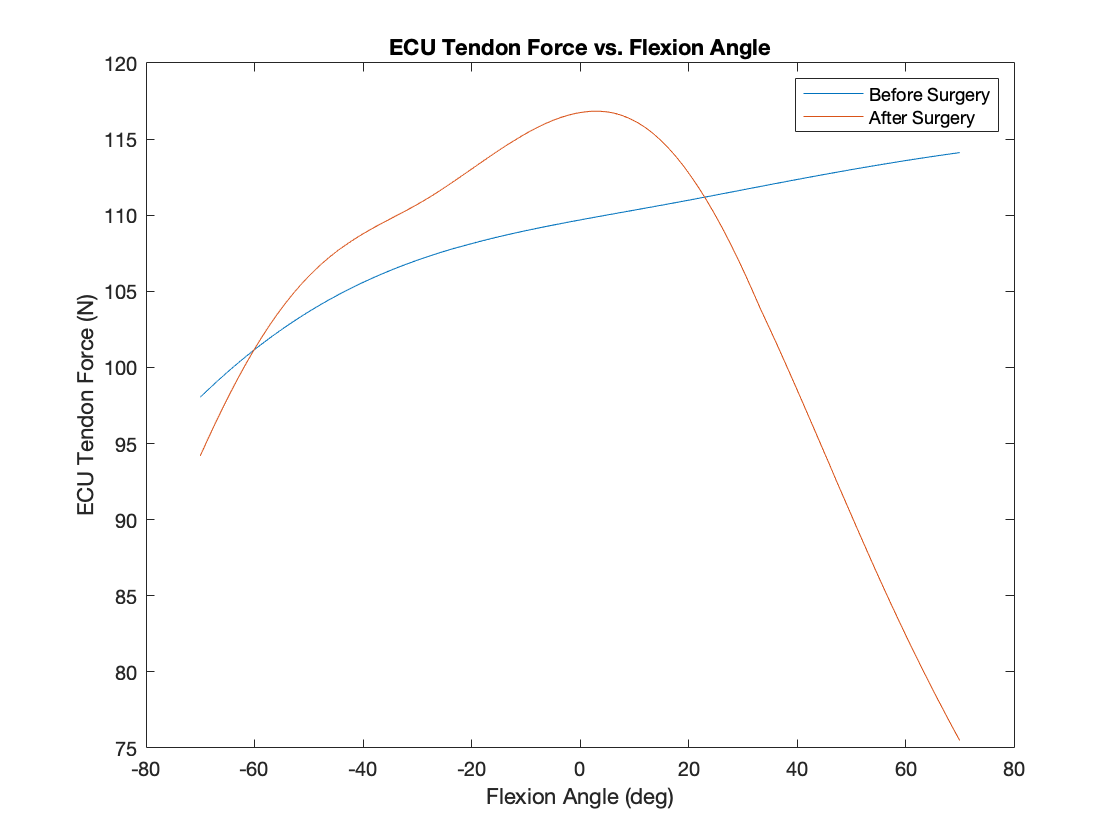


figure
x = t_ecuTF.x_jointset_Wrist_flexion_value;
y1 = t_ecuTF.BeforeSurgery;
y2 = t_ecuTF.AfterSurgery;
plot(x,y1)
hold on
plot(x,y2)
title('ECU Tendon Force vs. Flexion Angle')
ylabel('ECU Tendon Force (N)')
xlabel('Flexion Angle (deg)')
legend('Before Surgery','After Surgery')


[preMax,I] = max(y1);
preTheta = x(I);
[postMax,I] = max(y2);
postTheta = x(I);

t.Tendon_force = [preMax; postMax];
t.Tendon_force_angle = [preTheta; postTheta];

fileName = 'opensimTutorial2_EcuMomentArm.txt';
t_ecuMA = readtable(fileName);

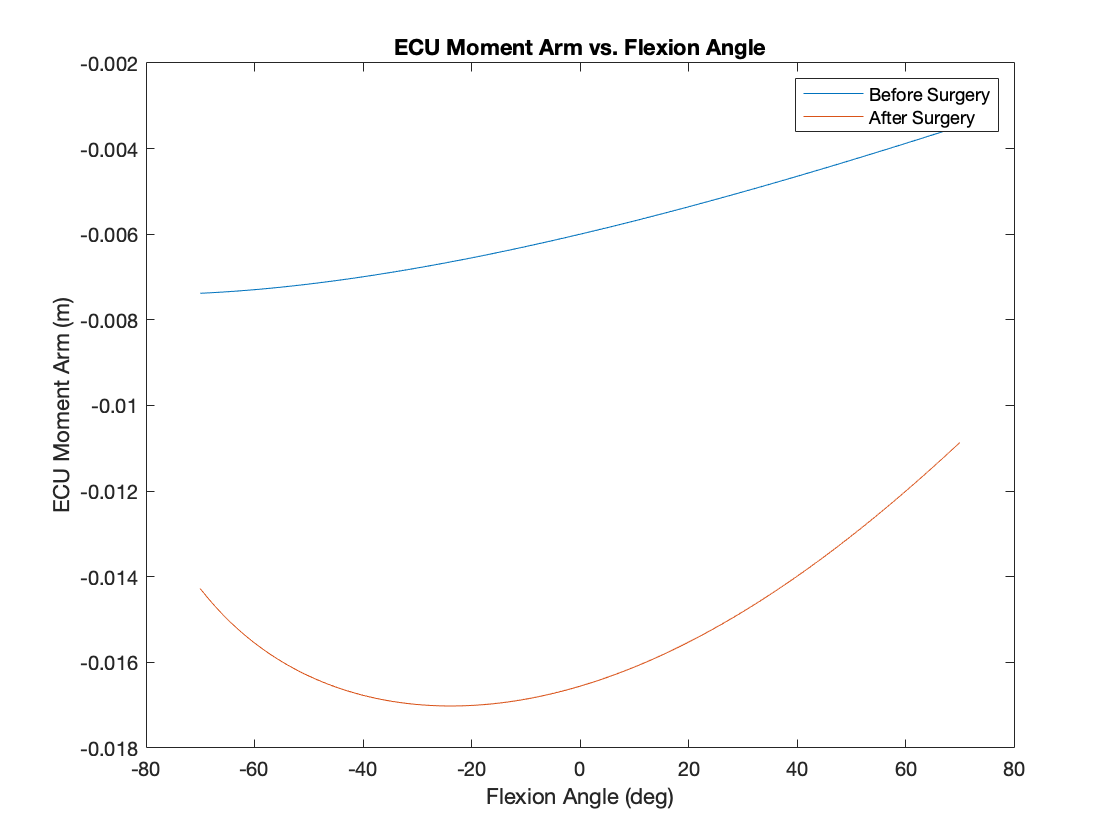


figure
x = t_ecuMA.x_jointset_Wrist_flexion_value;
y1 = t_ecuMA.BeforeSurgery;
y2 = t_ecuMA.AfterSurgery;
plot(x,y1)
hold on
plot(x,y2)
title('ECU Moment Arm vs. Flexion Angle')
ylabel('ECU Moment Arm (m)')
xlabel('Flexion Angle (deg)')
legend('Before Surgery','After Surgery')


[preMax,I] = min(y1);
preTheta = x(I);
[postMax,I] = min(y2);
postTheta = x(I);

t.Moment_arm = [preMax; postMax];
t.Moment_arm_angle = [preTheta; postTheta];

Q13 = t

Q13 = 2×6 table
                     Flexion_moment    Flexion_moment_angle    Tendon_force    Tendon_force_angle    Moment_arm    Moment_arm_angle
                     ______________    ____________________    ____________    __________________    __________    ________________

    BeforeSurgery       -0.7426              -50.202              114.11                 70          -0.0073791            -70     
    AfterSurgery        -1.9456              -7.7778              116.83             3.5354           -0.017019        -23.333     


14. What is the optimal fiber length of the ECU_pre-surgery muscle?  

Q14 = 0.0622

Q14 = 0.0622

15. What is the optimal fiber length of ECU_post-surgery?

Q15 = 0.0622

Q15 = 0.0622

16. Calculate the ratio of optimal fiber length to peak moment arm for ECU_pre-surgery and ECU_post-surgery.   

preRatio = 0.0622 / t.Moment_arm(1);
postRatio = 0.0622 / t.Moment_arm(2);
Q16 = [preRatio postRatio]

Q16 =    -8.4292   -3.6548


17. Explain the differences in the isometric moment vs. wrist flexion angle plots for the ECU_pre-surgery and ECU_post-surgery muscles, based on the plots of force and moment arm and the ratio of optimal fiber length to peak moment arm.  

Q17a = 'ECU pre surgery <moment, <moment arm, >fx at high flexion'

Q17a = 'ECU pre surgery <moment, <moment arm, >fx at high flexion'

Q17b = 'ECU post surgery >moment, >moment arm, >fx, but faster drop off'

Q17b = 'ECU post surgery >moment, >moment arm, >fx, but faster drop off'

% greater moment arm allows greater torque, but a greater change in
% fascicle length will be required per degree of joint rotation

 18. Specifically, what does the difference between the ratios of optimal fiber length to moment arm for the ECU before and after the tendon transfer tell you?

Q18 = 'smaller ratio = >torque, but >fascicle shortening per deg. rotation'

Q18 = 'smaller ratio = >torque, but >fascicle shortening per deg. rotation'

## V. The Effect of Tendon Slack Length on the Isometric Force-Angle Curve

19. What is the tendon slack length of the ECRB muscle?

Q19 = 0.2205

Q19 = 0.2205

20. What is the optimal fiber length of the ECRB muscle?

Q20 = 0.0585

Q20 = 0.0585

21. How did changing the tendon slack length of the ECRB alter the tendon force vs. flexion angle curve? 

Q21 = 'simillar peak, but occurs in extension rather than flexion'

Q21 = 'simillar peak, but occurs in extension rather than flexion'

22. How did changing the tendon slack length of the ECRB alter muscle-tendon length vs. flexion angle curve?

Q22 = 'unaffected'

Q22 = 'unaffected'

23. How did changing the tendon slack length of the ECRB alter the fiber length vs. flexion curve?

Q23 = 'increased fiber length at all angles'

Q23 = 'increased fiber length at all angles'

24. At what flexion angles do the fiber lengths of the ECRB and the edited ECRB reach the optimal fiber length? Compare these angles with the peaks of the force vs. flexion plots.

Q24 = [10 -25]

Q24 =     10   -25


25. Explain the effect of tendon slack length on the force-angle relationship of a muscle based on what you have learned about its effect on fiber length and muscle-tendon length.

Q25 = 'longer fibers, reach L_0 at shorter MTU lengths, peak force at shorter MTU lengths'

Q25 = 'longer fibers, reach L_0 at shorter MTU lengths, peak force at shorter MTU lengths'